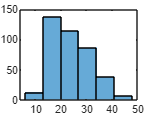

load carbig;
histogram(MPG, 6);

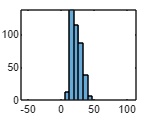

load EulerIdentity;
%figure('Renderer', 'painters', 'Position', [10 10 500 500]);
axis equal;

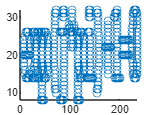


% plot(x, y);
scatter(x, y);

load humact.mat
D = feat; % [24075 x 60] matrix containing 60 feature measurements from 24075 samples
% compute eigvals
[~,~,eigvals] = pca(D);
% compute the cumulative_percent_variance_permode vector. 
cumulative_percent_variance_permode = 100*cumsum(eigvals) / sum(eigvals);
% Define N as the number of eigenvectors needed to capture at least 99.9% of the variation in D. 
N = find(cumulative_percent_variance_permode >= 99.9, 1)

N = 5

%size(dataset);
%[coeff,D_pca,latent] = pca(dataset);
%max(D_pca(:,1))
%max(D_pca(:,2))
%axis equal;
%scatter(D_pca(:,1), D_pca(:,2));

load fisheriris
D = meas(:,1:2); % [150 x 4] data feature matrix containing 4 features of 150 samples 
% compute D_pca and eigvals using the pca function
[eigvecs,D_pca,eigvals] = pca(D);
eigvals

eigvals =     0.6893
    0.1864


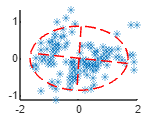

X = D;
X = X - mean(X); %zscore(D);
m = size(D,1);
[vec, val] = eig(X'*X / (m-1));
%D_pca(1,:)
%D(1,:)
P = X*eigvecs; % D_pca
%size(P)
%P(1,:)
scatter(D_pca(:,1), D_pca(:,2), '*');
hold on;
plot(eigvecs(1,1)*[2;-2]*sqrt(eigvals(1)), ...
    eigvecs(2,1)*[2;-2]*sqrt(eigvals(1)), 'r--')
plot(eigvecs(1,2)*[2;-2]*sqrt(eigvals(2)), ...
    eigvecs(2,2)*[2;-2]*sqrt(eigvals(2)), 'r--')
theta = 2*pi*[0:100]/100;
%ellipse_x = 2*sqrt(eigvals(1))*eigvecs(1,1)*cos(theta) + 2*sqrt(eigvals(2))*eigvecs(1,2)*sin(theta);
%ellipse_y = 2*sqrt(eigvals(1))*eigvecs(2,1)*cos(theta) + 2*sqrt(eigvals(2))*eigvecs(2,2)*sin(theta);
ellipse_x = 2*sqrt(eigvals(1))*cos(theta);
ellipse_y = 2*sqrt(eigvals(2))*sin(theta);
%Plot the ellipse with red dashed lines 'r--'
plot(ellipse_x, ellipse_y, 'r--')
hold off;

function mdl = my_fitpca(D,class)
% Find the number of unique classes from the class vector, numclasses
classes = unique(class);
numclasses = size(classes,1);
% For each class, use 'pca' to find the eigenvectors (1st output), eigenvalues (3rd output), and mean feature vector (6th output)
%mdl = struct('class',[]);
for i=1:numclasses
    cl = classes(i);
    [eigenvectors,~,eigenvalues,~,~,mu] = pca(D(class==cl,:));
    %D(class==cl, :)
    % create a subfield 'class' within the output struct mdl, which is a vector of length numclasses
    % mdl.class(i) has subfields 'eigvects' (the eigenvectors matrix output from 'pca', transposed), 'eigvals' (the eigenvalues output from 'pca'), and 'mu' (the mean feature vector).
    mdl.class(i) = struct('eigvects', eigenvectors', ...
                           'eigvals', eigenvalues, ...
                           'mu', mu);
end
end

D = [1 3 2 4;1 3 4 5]';

Function definitions in a script must appear at the end of the file.
Move all statements after the "my_fitpca" function definition to before the first local function definition.

class = [0;0;1;1];
mdl = my_fitpca(D,class);
mdl.class(1) % eigvects: [0.7071 0.7071]; eigvals: 4; mu: [2 2]
mdl.class(2) % eigvects: [0.8944 0.4472]; eigvals: 2.5000; mu: [3 4.5000];

D = [1 3 2 4 5 ;1 3 4 5 6; 6 3 2 1 7]';
class = [0;0;1;1;2];
mdl = my_fitpca(D,class);
mdl.class(1) % eigvects: [-0.4851 -0.4851 0.7276]; eigvals: 8.5000; mu: [2 2 4.5000]
mdl.class(2) % eigvects: [0.8165 0.4082 -0.4082]; eigvals: 3.0000; mu: [3 4.5000 1.5000]
mdl.class(3) % eigvects: [0×3 double]; eigvals: [0×1 double]; mu: [5 6 7] (We get empty eigvects and eigvals because with only one datapoint, there is no variability from the mean!)

load nodetraffic;
mu = mean(nodetraffic)
s = std(nodetraffic)
size(nodetraffic(nodetraffic > mu + 6*s | nodetraffic < mu - 6*s))

function [md,b,std_per_mode] = MahalanobisDistance(pcamdl,v)
% compute b, our PCA coordinates for v
%size(pcamdl.eigvects)
%size(v - pcamdl.mu)
b = (v - pcamdl.mu)*pcamdl.eigvects';
% compute D, the standard deviation distance from the mean for v for each mode of variation
std_per_mode = abs(b) ./ sqrt(pcamdl.eigvals);
% compute md, the Mahalanobis distance
md = sqrt(sum(std_per_mode.^2));
end

mdl.class(1).eigvects = [0.7071 0.7071]; 
mdl.class(1).eigvals = 4; 
mdl.class(1).mu = [2 2];
v = [2,2];
md = MahalanobisDistance(mdl.class(1),v) % md = 0 because v = mu
v = [2,2] + 2*[0.7071 0.7071];
md = MahalanobisDistance(mdl.class(1),v) % md = 1 because v is 2/sqrt(eigval)=2/2=1 standard deviations from mean along eigenvector
v = [2,2] - 6*[0.7071 0.7071];
md = MahalanobisDistance(mdl.class(1),v) % md = 3 because v is 6/sqrt(eigval)=6/2=3 standard deviations from mean along eigenvector
v = [2,2] + [-0.7071 0.7071];
md = MahalanobisDistance(mdl.class(1),v) % md = 0 because v lies in a direction from mu that is orthogonal to the eigenvector

function md = MahalanobisDistance2(pcamdl,v)
% compute b, our PCA coordinates for v
b = (v - pcamdl.mu)*pcamdl.eigvects';
% compute D, the standard deviation distance from the mean for v for each mode of variation
std_per_mode = abs(b) ./ sqrt(pcamdl.eigvals');
%size(b)
%size(std_per_mode)
% compute md, the Mahalanobis distance
md = sqrt(sum(std_per_mode.^2));
end

function [class,score] = my_predictpca(mdl,data)
% Initialize output 'class' and 'score' to Mx1 zero vectors
[M, ~] = size(data);
class = zeros(M,1);
score = zeros(M,1);
% Loop over the M samples, to classify each 'i'th sample
for i=1:M
% In a nested loop, loop over each 'j'th class to compare the 'i'th sample to the 'j'th class.
mdscore = zeros(length(mdl.class),1);
for j=1:length(mdl.class)
% Within the loop, find the Mahalanobis distance from the 'i'th sample feature vector to the 'j'th
%j
%mdl.class(j)
%data(i,:)
mdscore(j) = MahalanobisDistance2(mdl.class(j), data(i,:));
end
% The minimium Mahalanobis distance across the class pca models is used to choose our classification fo
% The classification and the Mahalanobis distance are stored in class(i) and score(i)
[score(i), class(i)] = min(mdscore);
end
end

load humact.mat
D_train = feat(1:2:end,:);
class_train = actid(1:2:end);
D_test = feat(2:2:end,:);
class_test = actid(2:2:end);
size(D_train)
size(D_test)
mdl = my_fitpca(D_train,class_train)
%mdl.class(1)
%MahalanobisDistance(mdl.class(1), D_test(1,:))
[class, score] = my_predictpca(mdl,D_test);
mean(class_test == class)

load carbig
D = [Acceleration, Cylinders, Displacement, Horsepower, Model_Year, Weight];
y = MPG;
msk = ~ismissing(y);
D = D(msk,:);
y = y(msk);
D_train  = D(1:2:end,:);
y_train = y(1:2:end);
D_test = D(2:2:end,:);
y_test = y(2:2:end);
rng(0);
mdl = fitrtree(D_train, y_train, 'OptimizeHyperparameters','auto');

%mdl = fitrtree([D_train; D_test], [y_train; y_test], 'OptimizeHyperparameters','auto');
y_pred = predict(mdl, D_test);
mean((y_test - y_pred).^2)

rng(0);
mdl = fitrgp(D_train, y_train, 'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'));
%mdl = fitrtree([D_train; D_test], [y_train; y_test], 'OptimizeHyperparameters','auto');
y_pred = predict(mdl, D_test);
mean((y_test - y_pred).^2)

img = imread('logo.tif');
imagesc(img(30:50, 20:90));

load RGB.mat;
img(:,:,1) = R;
img(:,:,2) = G;
img(:,:,3) = B;
imagesc(img);


load convhull.mat;
imagesc(bwconvhull(msk));

imagesc(bwconvhull(msk, 'objects'));

img = imread('cameraman.tif');
msk = img<=88;
msk_erode = imerode(msk,ones(7,7));
msk_open = imdilate(msk_erode,ones(7,7));
subplot(2,2,1); imagesc(img);
subplot(2,2,2); imagesc(msk);
subplot(2,2,3); imagesc(msk_erode);
subplot(2,2,4); imagesc(msk_open);

clf;
img = imread('cameraman.tif');
filt = fspecial('motion');
img_filt = conv2(img, filt, 'same');
imagesc(img_filt);

mean(mean(img_filt))
T = 3;
Fs = 44100;
f = [330, 27, 208, 165, 123, 82];
% Compute time vector, t
t = [0:1/Fs:T-1/Fs];
% Use a for-loop to construct y as a sum of cosines
y = zeros(size(t));
for i=1:numel(f)
y = y + cos(2*pi*f(i)*t);
end
soundsc(y, Fs);
x = [1:0.5:5.5]
N = length(x);
xFs = 2;
yFs = 1;
% Find the total time duration 'T'
T = (length(x)-1) / xFs;
T = 4.5000
% Using 'T', define a time vector 'tx'
tx = [0:1/xFs:T];
length(tx)
% Using 'T', define the new time vector, 'ty' for our resampled time. 
ty = [0:1/yFs:T];
% Use interp1 to create y by resampling x
y = interp1(tx, x, ty, 'linear');

clear;
load ReverseAudio.mat;
y = flipud(y_rev);
soundsc(y, Fs);
[m, idx] = max(y)
m = 0.2158
idx = 143068
Fs=10;
x1 = repmat([1 0 -1 0],[1,10]); % this is a 2.5 Hz signal
x2 = repmat([1 -1],[1,20]); % this is a 5 Hz signal
x = x1 + x2;
freq_range = [2,3]; % filter out the 5 Hz but keep the 2.5 Hz component
W = 10;
%Create the filter using 'fir1'
freq_range = freq_range / (Fs / 2);
filt = fir1(W,freq_range);
%Apply the filter using 'conv'
y = conv(x, filt, 'same');
% plot x1, x2, x=x1+x2, and BandPassFilter output
t = 0:1/Fs:(length(y)-1)/Fs;
plot(t(1:Fs),x1(1:Fs),'bo-')
hold on
plot(t(1:Fs),x2(1:Fs),'r*-')
plot(t(1:Fs),x(1:Fs),'g')
plot(t(1:Fs),y(1:Fs),'m--', 'LineWidth', 2)
legend('x1-2.5Hz','x2-5.0Hz','x=x1+x2','output')

x = [0 0 0 1 0 0 0]; 
sigma = 1.5;
% Compute W by rounding up 6*sigma
W = round(6*sigma);
% Use fspecial to create our Gaussian filter
filt = fspecial("gaussian", [W, 1], sigma);
% convolve the signal with the filter
y = conv(x, filt, 'same')

load gong % loads gong sound y and sampling frequency Fs
% can play in MATLAB Online with soundsc(y,Fs)
soundsc(y,Fs)
% call spectrogram to get s,f,t
[s, f, t] = spectrogram(y, 256, [], [], Fs);
% Use imagesc to display it
imagesc(f, t, log(abs(s')));

function [yfft, f] = myfft(y,Fs)
%compute the standard fft
yfft = fft(y);
%trim away the redundant part
yfft = yfft(1:ceil((length(y)+1)/2));
%compute the frequencies to which each fft entry corresponds.
sampnum = [0:(length(yfft)-1)]';
f = sampnum * Fs / length(y);
end

function y = myifft(yfft, f, Fs)
% Replace redundant part of the fft that we trimmed away:
% if the last frequency in f equals Fs/2,
if f(end) == Fs/2
% then we need to append the conjugate of the mirrored entries in yfft from 2 to length of yfft minus
y = [yfft; conj(flipud(yfft(2:end-1)))];
% else
else
% then we need to append the conjugate of the mirrored entries in yfft from 2 to length of yfft
y = [yfft; conj(flipud(yfft(2:end)))];
end
% perform ifft
y = ifft(y);
end

load crickets.mat;
[yfft, f] = myfft(crickets,Fs);
plot(f, abs(yfft), '*');

Fs = 1000;
freq_range = [100,200];
filt10 = fir1(10,freq_range/(Fs/2));
filt100 = fir1(100,freq_range/(Fs/2));
filt1000 = fir1(1000,freq_range/(Fs/2));
%plot(crickets(1:100));
plot(filt10);

[yfft, f] = myfft(filt10,Fs);
[~,i] = min(abs(f-90));
abs(yfft(i))
ans = 0.7722
plot(f, abs(yfft), '*');

plot(filt100);

[yfft, f] = myfft(filt100,Fs);
[~,i] = min(abs(f-90));
abs(yfft(i))
ans = 0.0594
plot(f, abs(yfft), '*');

plot(filt1000);

[yfft, f] = myfft(filt1000,Fs);
[~,i] = min(abs(f-90));
abs(yfft(i))
ans = 6.8140e-04
plot(f, abs(yfft), '*');

function mask = OtsuThreshold(img)
mask = img > otsuthresh(img);
end